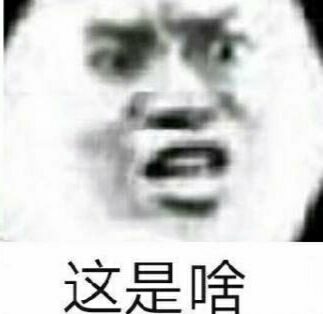

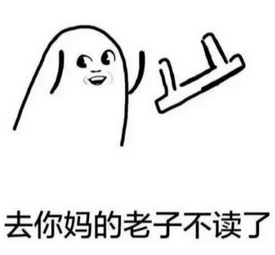

## 辣鸡第八题,毁我青春

### 首先算精确解

clc,clear;
A_matrix=[0.5 1 2;
          1/3 1/4 1/5;
          1/4 1/5 1/6];
B_matrix=[7 8 9]';
RealAns=A_matrix^(-1)*B_matrix

RealAns =  -227.5385
  478.4615
 -178.8462


sym(RealAns)

$$ans = \left(\begin{array}{c} -\frac{2958}{13}\\ \frac{6220}{13}\\ -\frac{2325}{13} \end{array}\right)$$

### 高斯消元法,每一步截取五位有效数字

digits(5) 
Ori_matrix=[0.25 0.2 0.16667 9;
            0.33333 0.25 0.2 8;
            0.5 1 2 7];
vpa(Ori_matrix,21)

$$ans = \left(\begin{array}{cccc} 0.25 & 0.2 & 0.16667 & 9.0\\ 0.33333 & 0.25 & 0.2 & 8.0\\ 0.5 & 1.0 & 2.0 & 7.0 \end{array}\right)$$

FirstStep=double(vpa(OneStepGaoSi(Ori_matrix),5));
vpa(FirstStep,9)%可以看到按照这种操作,可以截取矩阵每个元素保留4位有效数字

$$ans = \left(\begin{array}{cccc} 0.25 & 0.2 & 0.16667 & 9.0\\ 0 & -0.016664 & -0.022224 & -3.9999\\ 0 & 0.6 & 1.6667 & -11.0 \end{array}\right)$$

FirstStep(2:end,2:end)=double(vpa(OneStepGaoSi(FirstStep(2:end,2:end)),5));
vpa(FirstStep,9)

$$ans = \left(\begin{array}{cccc} 0.25 & 0.2 & 0.16667 & 9.0\\ 0 & -0.016664 & -0.022224 & -3.9999\\ 0 & 0 & 0.86651 & -155.02 \end{array}\right)$$

A=FirstStep(:,1:end-1);
b=FirstStep(:,end);
digits(5) 
x3=vpa(b(3)/A(3,3),5)%用vpa截取x3的5位有效数字

$$x3 = -178.9$$

x3=vpa(x3,9)%可以看出直接截取sym型的x3是不行的

$$x3 = -178.901571$$

x3=vpa(double(x3),5)%先变成double()然后vpa可以截取

$$x3 = -178.9$$

vpa(x3,9)%可以看出确实截取了

$$ans = -178.9$$

x2=vpa((b(2)-A(2,3)*x3)/A(2,2),5)

$$x2 = 478.62$$

x2=vpa(double(x2),5);
x1=vpa((b(1)-A(1,2)*x2-A(1,3)*x3)/A(1,1),5)

$$x1 = -227.63$$

x1=vpa(double(x1),5);
Method1Ans=[x1;x2;x3];


列主元消去法

Ori_matrix=[0.5 1 2 7;
            0.33333 0.25 0.2 8;
            0.25 0.2 0.16667 9];
vpa(Ori_matrix,5)

$$ans = \left(\begin{array}{cccc} 0.5 & 1.0 & 2.0 & 7.0\\ 0.33333 & 0.25 & 0.2 & 8.0\\ 0.25 & 0.2 & 0.16667 & 9.0 \end{array}\right)$$

FirstStep=double(vpa(OneStepGaoSi(Ori_matrix),5));
vpa(FirstStep,9)%可以看到按照这种操作,可以截取矩阵每个元素保留4位有效数字

$$ans = \left(\begin{array}{cccc} 0.5 & 1.0 & 2.0 & 7.0\\ 0 & -0.41666 & -1.1333 & 3.3334\\ 0 & -0.3 & -0.83333 & 5.5 \end{array}\right)$$

FirstStep(2:end,2:end)=double(vpa(OneStepGaoSi(FirstStep(2:end,2:end)),5));
vpa(FirstStep,9)

$$ans = \left(\begin{array}{cccc} 0.5 & 1.0 & 2.0 & 7.0\\ 0 & -0.41666 & -1.1333 & 3.3334\\ 0 & 0 & -0.017341 & 3.0999 \end{array}\right)$$

A=FirstStep(:,1:end-1);
b=FirstStep(:,end);
x3=vpa(b(3)/A(3,3),5)%用vpa截取x3的5位有效数字

$$x3 = -178.76$$

x1=vpa(double(x1),5);
x2=vpa((b(2)-A(2,3)*x3)/A(2,2),5)

$$x2 = 478.22$$

x2=vpa(double(x2),5);
x1=vpa((b(1)-A(1,2)*x2-A(1,3)*x3)/A(1,1),5)

$$x1 = -227.39$$

x1=vpa(double(x1),5);
Method2Ans=[x1;x2;x3];

比较两种解的精确性


norm(RealAns-vpa(Method1Ans,5))

$$ans = 0.19076$$

norm(RealAns-vpa(Method2Ans,5))

$$ans = 0.29594$$

可以看到高斯消元更好

以下不用写

y1=A_matrix*Method1Ans

$$y1 = \left(\begin{array}{c} 7.005\\ 7.9983\\ 8.9998 \end{array}\right)$$

y2=A_matrix*Method2Ans

$$y2 = \left(\begin{array}{c} 7.0024\\ 8.0061\\ 9.0029 \end{array}\right)$$

norm(y1-[9 8 7]')

$$ans = 2.8248$$

norm(y2-[9 8 7]')

$$ans = 2.8288$$

clc,clear;
sym(9/8+3/8*207/434)

$$ans = \frac{4527}{3472}$$

sym(3+4527/3472/3)

$$ans = \frac{11925}{3472}$$

A=[3 -1 0 0 0;
 -1 3 -1 0 0;
 0 -1 3 -1 0;
 0 0 -1 3 -1;
 0 0 0 -1 3];
b=[1 0 1 0 0]';
A^(-1)*b

ans =     0.4375
    0.3125
    0.5000
    0.1875
    0.0625


[L,U]=lu(A);
U=sym(U')

$$U = \left(\begin{array}{ccccc} 3 & 0 & 0 & 0 & 0\\ -1 & \frac{8}{3} & 0 & 0 & 0\\ 0 & -1 & \frac{21}{8} & 0 & 0\\ 0 & 0 & -1 & \frac{55}{21} & 0\\ 0 & 0 & 0 & -1 & \frac{144}{55} \end{array}\right)$$

L=sym(L')

$$L = \left(\begin{array}{ccccc} 1 & -\frac{1}{3} & 0 & 0 & 0\\ 0 & 1 & -\frac{3}{8} & 0 & 0\\ 0 & 0 & 1 & -\frac{8}{21} & 0\\ 0 & 0 & 0 & 1 & -\frac{21}{55}\\ 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

y=U^(-1)*b

$$y = \left(\begin{array}{c} \frac{1}{3}\\ \frac{1}{8}\\ \frac{3}{7}\\ \frac{9}{55}\\ \frac{1}{16} \end{array}\right)$$

L^(-1)*y

$$ans = \left(\begin{array}{c} \frac{7}{16}\\ \frac{5}{16}\\ \frac{1}{2}\\ \frac{3}{16}\\ \frac{1}{16} \end{array}\right)$$

clc,clear;
syms l21 l31 l32 d1 d2 d3;
L=[1 0 0;
    l21 1 0;
    l31 l32 1];
D=diag([d1,d2,d3]);
L*D*L'

$$ans = \left(\begin{array}{ccc} d_{1} & d_{1}\,\bar{l_{21}} & d_{1}\,\bar{l_{31}}\\ d_{1}\,l_{21} & d_{2}+d_{1}\,l_{21}\,\bar{l_{21}} & d_{2}\,\bar{l_{32}}+d_{1}\,l_{21}\,\bar{l_{31}}\\ d_{1}\,l_{31} & d_{2}\,l_{32}+d_{1}\,l_{31}\,\bar{l_{21}} & d_{3}+d_{1}\,l_{31}\,\bar{l_{31}}+d_{2}\,l_{32}\,\bar{l_{32}} \end{array}\right)$$

A=[2 -1 1;
-1 -2 3;
1 3 1];
exp=A-L*D*L'==0;
solution=solve(exp,[l21 l31 l32 d1 d2 d3]);
fileds = fieldnames(solution);

for i=1:length(fileds)
    k = fileds(i);
    key = k{1};
    value = solution.(key);
    eval([key,'=value;']);%重要方法,把字符串转化为变量,执行赋值语句
    fprintf('%s=%s\n',key,value)
end

l21=-1/2
l31=1/2
l32=-7/5
d1=2
d2=-5/2
d3=27/5


L=[1 0 0;
    l21 1 0;
    l31 l32 1]

$$L = \left(\begin{array}{ccc} 1 & 0 & 0\\ -\frac{1}{2} & 1 & 0\\ \frac{1}{2} & -\frac{7}{5} & 1 \end{array}\right)$$

D=diag([d1,d2,d3])

$$D = \left(\begin{array}{ccc} 2 & 0 & 0\\ 0 & -\frac{5}{2} & 0\\ 0 & 0 & \frac{27}{5} \end{array}\right)$$

b=[6 5 4]';
y=L^(-1)*b

$$y = \left(\begin{array}{c} 6\\ 8\\ \frac{61}{5} \end{array}\right)$$

(L*D*L')^(-1)*b

$$ans = \left(\begin{array}{c} \frac{50}{27}\\ -\frac{1}{27}\\ \frac{61}{27} \end{array}\right)$$

clc,clear;
A=[0.6 0.5;0.4 0.3];
ATA=A'*A

ATA =     0.5200    0.4200
    0.4200    0.3400


simplify(sym((0.36+0.25+0.16+0.09)^0.5))

$$ans = \frac{\sqrt{86}}{10}$$

sym(eig(ATA))

$$ans = \left(\begin{array}{c} \frac{4191663218897}{9007199254740992}\\ \frac{1935499923964589}{2251799813685248} \end{array}\right)$$

syms l;
eq=det(diag([l,l])-ATA)  

$$eq = l^{2}-\frac{43\,l}{50}+\frac{1}{2500}$$

answ=solve(eq,l)

$$answ = \left(\begin{array}{c} \frac{43}{100}-\frac{3\,\sqrt{5}\,\sqrt{41}}{100}\\ \frac{3\,\sqrt{5}\,\sqrt{41}}{100}+\frac{43}{100} \end{array}\right)$$

max(answ)^0.5

$$ans = \sqrt{\frac{3\,\sqrt{5}\,\sqrt{41}}{100}+\frac{43}{100}}$$

simplify(max(answ)^0.5)%用simplify分母有理化

$$ans = \frac{3\,\sqrt{10}}{20}+\frac{\sqrt{82}}{20}$$

vpa(max(answ)^0.5,9)

$$ans = 0.927110906$$

sym([100 99;99 97]^(-1))

$$ans = \left(\begin{array}{cc} -\frac{97}{101} & \frac{99}{101}\\ \frac{99}{101} & -\frac{100}{101} \end{array}\right)$$

A=[100 99;99 97];
ATA=A'*A

ATA =        19801       19503
       19503       19210


syms l;
eq=det(diag([l,l])-ATA);  
answ=solve(eq,l)

$$answ = \left(\begin{array}{c} \frac{39011}{2}-\frac{591\,\sqrt{4357}}{2}\\ \frac{591\,\sqrt{4357}}{2}+\frac{39011}{2} \end{array}\right)$$

double(answ)

ans = 	1.0e+04 *

    0.0000
    3.9011


(max(answ)/min(answ))^0.5

$$ans = \sqrt{-\frac{\frac{591\,\sqrt{4357}}{2}+\frac{39011}{2}}{\frac{591\,\sqrt{4357}}{2}-\frac{39011}{2}}}$$

simplify((max(answ)/min(answ))^0.5)

$$ans = \frac{591\,\sqrt{4357}}{202}+\frac{39011}{202}$$

vpa(double((max(answ)/min(answ))^0.5),9)

$$ans = 386.24$$

syms l;
eq=det(diag([l,l])-A);  
answ=solve(eq,l)

$$answ = \left(\begin{array}{c} \frac{197}{2}-\frac{3\,\sqrt{4357}}{2}\\ \frac{3\,\sqrt{4357}}{2}+\frac{197}{2} \end{array}\right)$$

double(answ)

ans =    -0.5114
  197.5100


(max(answ)/min(answ))

$$ans = -\frac{\frac{3\,\sqrt{4357}}{2}+\frac{197}{2}}{\frac{3\,\sqrt{4357}}{2}-\frac{197}{2}}$$

simplify((max(answ)/min(answ)))

$$ans = -\frac{591\,\sqrt{4357}}{202}-\frac{39011}{202}$$

simplify(max(answ)/min(answ))

$$ans = \frac{23055501\,\sqrt{4357}}{20402}+\frac{1521837719}{20402}$$

syms a b;
ep = (a*sqrt(4357)+b)^2==simplify(max(answ)/min(answ))

$$ep = {\left(b+\sqrt{4357}\,a\right)}^{2}=\frac{23055501\,\sqrt{4357}}{20402}+\frac{1521837719}{20402}$$

ab=solve(ep,[a b])

ab = 包含以下字段的 struct :
    a: [2×1 sym]
    b: [2×1 sym]


ab.b

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

a=simplify((max(answ)/min(answ))^0.5)

$$a = \frac{591\,\sqrt{4357}}{202}+\frac{39011}{202}$$

a=simplify(a^0.5)

$$a = \frac{197\,\sqrt{101}}{202}+\frac{3\,\sqrt{440057}}{202}$$

a=simplify(a^0.5)

$$a = \sqrt{\frac{197\,\sqrt{101}}{202}+\frac{3\,\sqrt{440057}}{202}}$$

a=simplify(a^0.5)

$$a = {\left(\frac{197\,\sqrt{101}}{202}+\frac{3\,\sqrt{440057}}{202}\right)}^{1/4}$$

expand(a^2)

$$ans = \sqrt{\frac{197\,\sqrt{101}}{202}+\frac{3\,\sqrt{440057}}{202}}$$